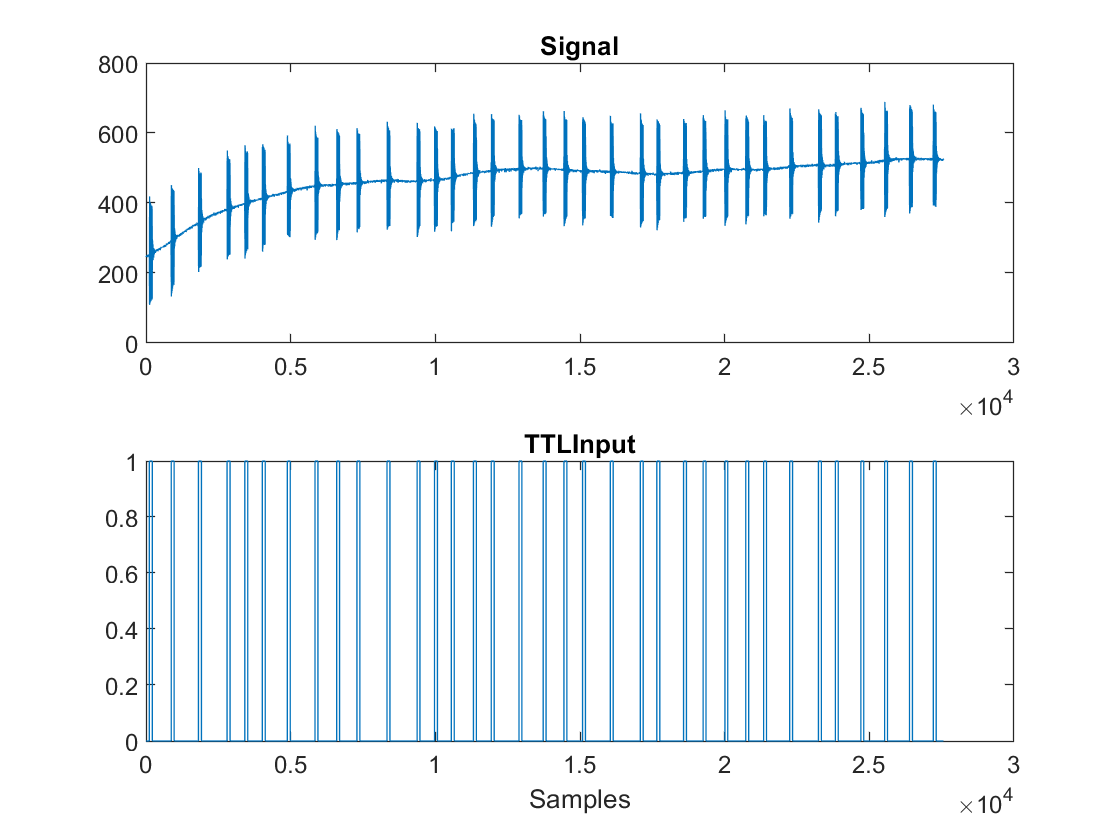

signal = double(signal);
TTLInput = states.TTLInput;

figure;
subplot(2,1,1); % First subplot for the Signal
plot(signal);
title('Signal');

subplot(2,1,2); % Second subplot for the TTLInput
stairs(TTLInput); % Using stairs because TTL is typically a step function
title('TTLInput');
xlabel('Samples');



% Thresholding method to detect onset. This might need adjustments.
threshold_signal = 400; %**************************************************************
threshold_ttl = 0.5; % Assuming TTL goes from 0 to 1, so halfway is 0.5


min_distance = 50;  % This value may need adjustment based on the data frequency and characteristics
all_events_signal = find(diff(signal > threshold_signal) == 1);
onsets_signal = all_events_signal([true; diff(all_events_signal) > min_distance]);
%onsets_signal = find(diff(signal > threshold_signal) == 1);

onsets_ttl = find(diff(TTLInput > threshold_ttl) == 1);

% Make sure you have an equal number of onsets for both Signal and TTLInput
min_length = min(length(onsets_signal), length(onsets_ttl));

% Compute latency/jitter
latency = onsets_signal(1:min_length) - onsets_ttl(1:min_length);

% To see the results:
mean_latency = mean(latency);
std_latency = std(latency);

fprintf('Mean Latency: %f, Jitter: %f\n', mean_latency, std_latency);

Mean Latency: 4.685714, Jitter: 2.233059


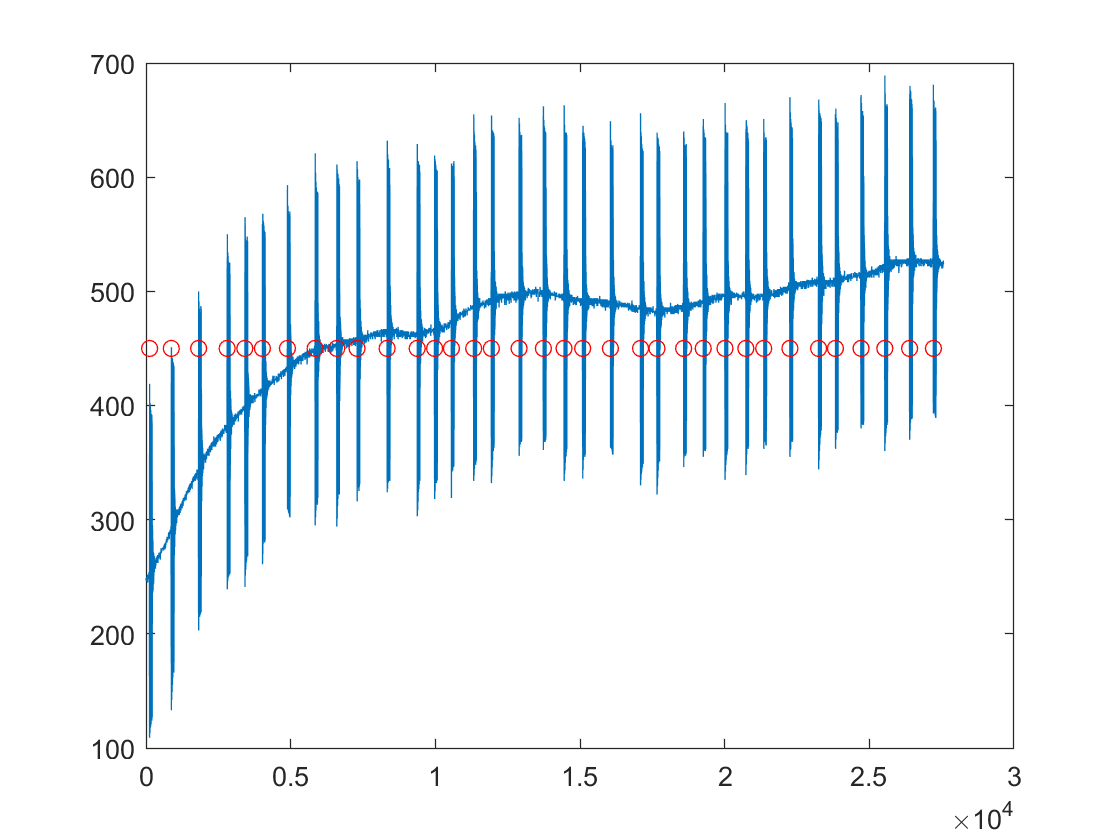


%show the onset of the signal 
figure;
plot(signal);
hold on;
plot(onsets_signal, ones(numel(onsets_signal))*450,'or');



Fs = parms.SamplingRate.NumericValue; 
Ts = 1000 / Fs;

fprintf('Sample reat: %f ms', Ts);

Sample reat: 1.000000 ms

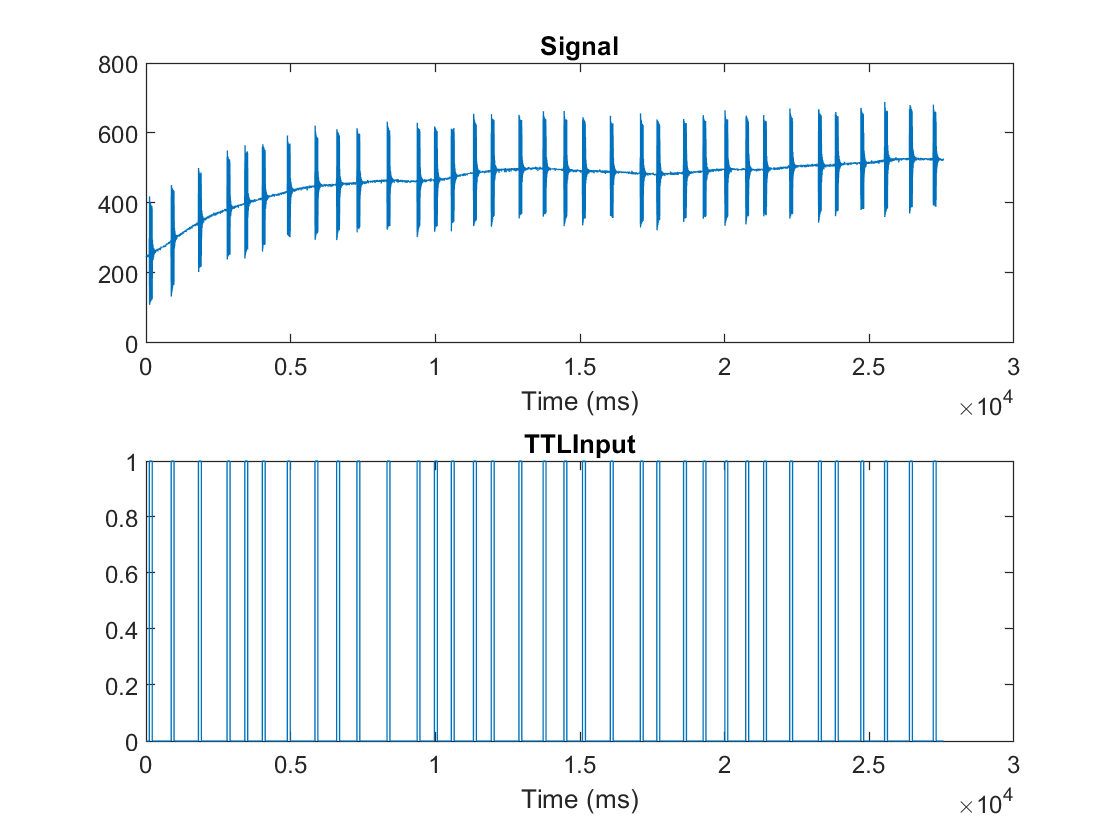


% Create a time vector for the x-axis
time_vector = (0:length(signal)-1) * Ts;

figure;
subplot(2,1,1); % First subplot for the Signal
plot(time_vector, signal);  % Use time_vector for x-axis
title('Signal');
xlabel('Time (ms)');

subplot(2,1,2); % Second subplot for the TTLInput
stairs(time_vector, TTLInput);  % Use time_vector for x-axis
title('TTLInput');
xlabel('Time (ms)');



% Convert onsets from samples to milliseconds
onsets_signal_ms = onsets_signal * Ts;
onsets_ttl_ms = onsets_ttl * Ts;

%latency in milliseconds
latency_ms = onsets_signal_ms(1:min_length) - onsets_ttl_ms(1:min_length);

%jitter in milliseconds
jitter_ms = std(latency_ms);

mean_latency_ms = mean(latency_ms);
fprintf('Mean Latency: %f ms, Jitter: %f ms\n', mean_latency_ms, jitter_ms);

Mean Latency: 4.685714 ms, Jitter: 2.233059 ms


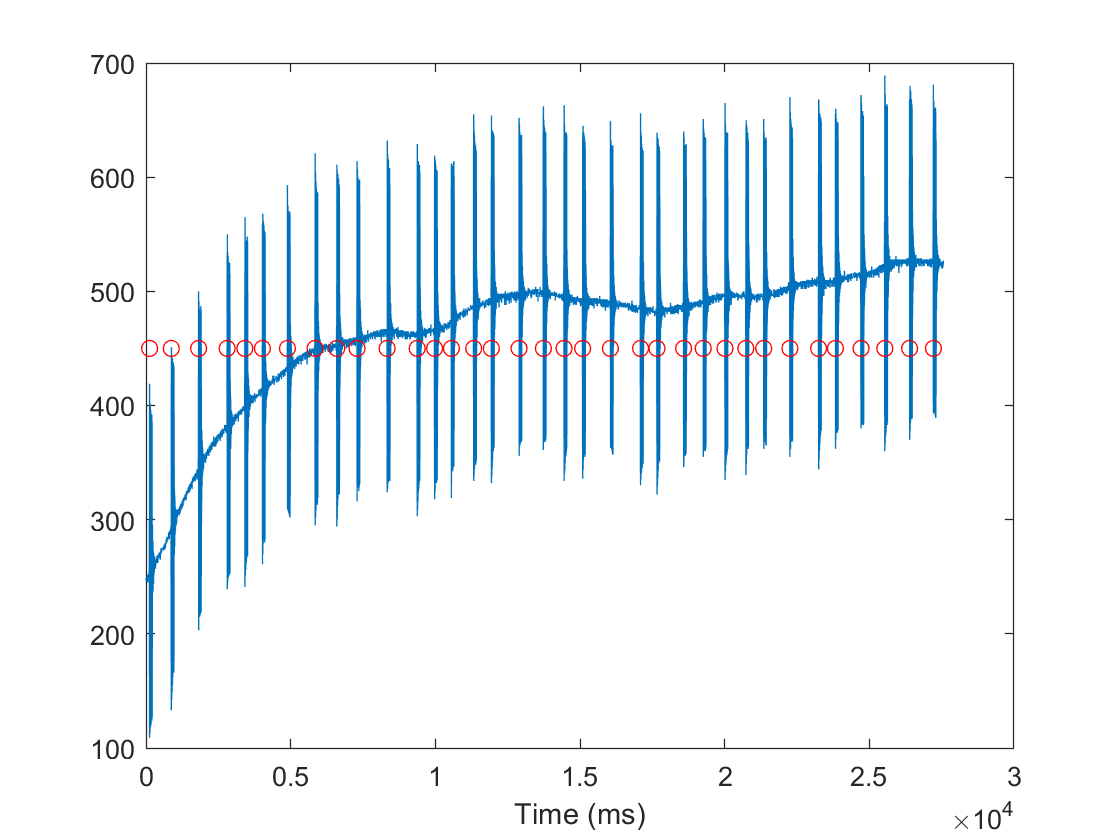


% Plotting the signal with onsets
figure;
plot(time_vector, signal);
hold on;
plot(onsets_signal_ms, ones(numel(onsets_signal))*450, 'or');
xlabel('Time (ms)');